# Filtering: Denoising

In this example, we will use some Matlab functions for denoising noisy signals. 

% Clear workspace and command window
clear;
clc;

## AWGN noise

A basic and generally accepted noise model is known as Additive White Gaussian Noise (AWGN), which imitates various random processes seen in nature. It is additive since noise is added to a signal. Moreover, the noise is uncorrelated, meaning the occurrence of one sample does not affect the probability of occurrence of the other. White, because the noise has the same power distribution at every frequency and Gaussian, so each sample has a normal distribution with zero mean and given variance.

We generate a simple sum of two sinosudal wave signals and add an AWGN noise with a given standard deviation. 

The function [`randn`](https://it.mathworks.com/help/matlab/ref/randn.html) generate a normally distribute random number with zero mean and unit standard deviation.

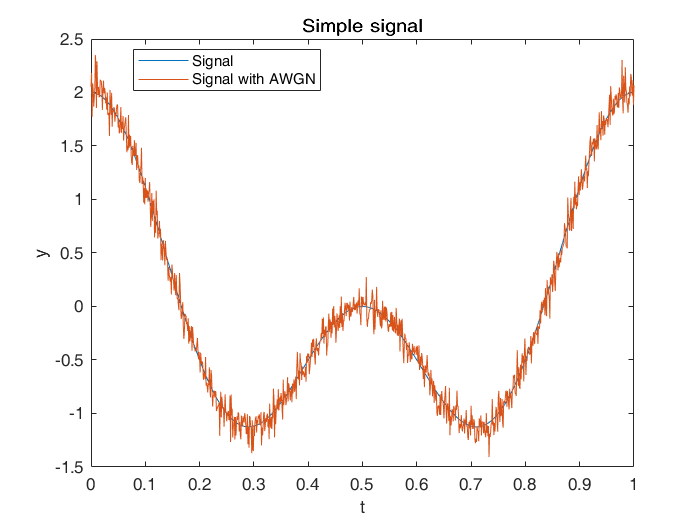

t = 0:0.001:1;
noise_std = 0.1;

x = cos(2*pi*t) + cos(2*pi*2*t);
noise = noise_std .* randn(size(t));
x_noise = x + noise;

plot(t,x,t,x_noise);
title('Simple signal')
legend('Signal','Signal with AWGN','location','best');
xlabel('t');
ylabel('y');

Using a moving average filter, with a suitable windows size we can smooth out the high-speed wind gusts by averaging n samples of the signal.

The function [`smoothdata`](https://it.mathworks.com/help/matlab/ref/smoothdata.html) returns the result of moving mean filter on the speed signal, where each means is calculated over a sliding window of a given length`.`

window =15

window = 15

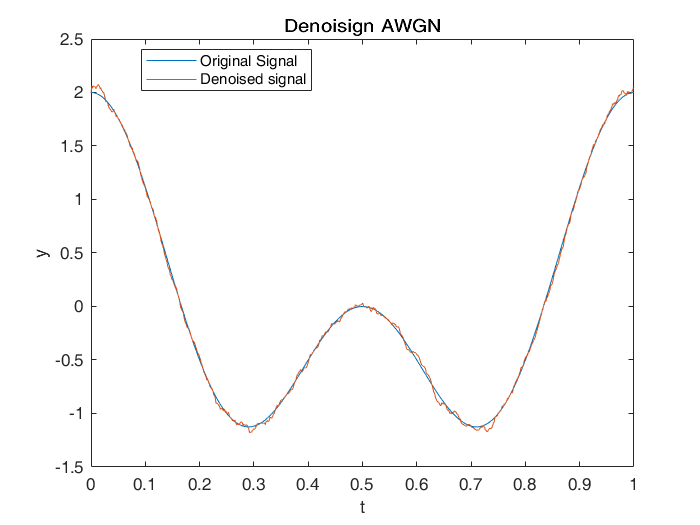

method = 'movmean';
x_denoised = smoothdata(x_noise,method,window);

plot(t,x,t,x_denoised);
title('Denoisign AWGN')
legend('Original Signal','Denoised signal','location','best');
xlabel('t');
ylabel('y');

## Impulsive noise (spikes)

Impulse noise is characterized by unwanted, almost instantaneous impulse-like disturbance in the signal.

Consider the open-loop voltage across the input of an analog instrument in the presence of 60 Hz power-line noise. The sample rate is 1 kHz.

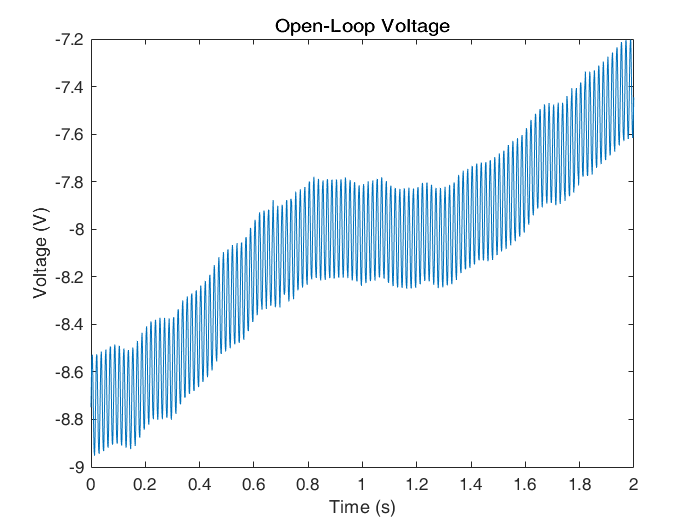

load openloop60hertz

fs = 1000;
t = (0:numel(openLoopVoltage) - 1)/fs;

plot(t,openLoopVoltage)

xlabel('Time (s)')
ylabel('Voltage (V)')
title('Open-Loop Voltage')

We insert some spikes into the signal to simulate the impulsive noise:

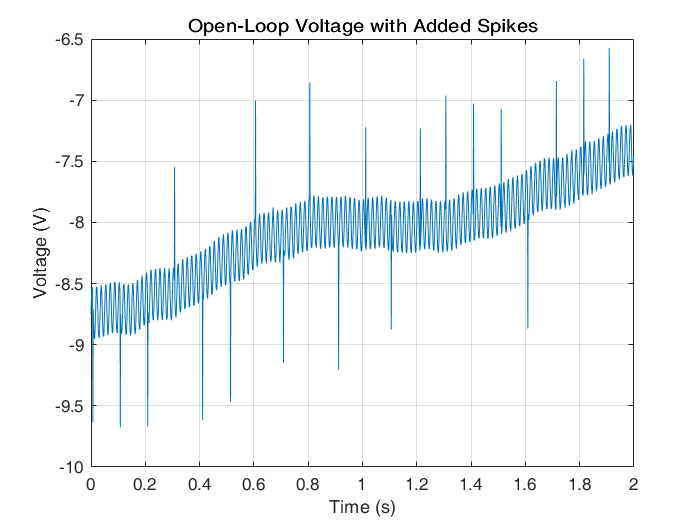

spikeSignal = zeros(size(openLoopVoltage));
spks = 10:100:1990;
spikeSignal(spks+round(2*randn(size(spks)))) = sign(randn(size(spks)));

noisyLoopVoltage = openLoopVoltage + spikeSignal;

plot(t,noisyLoopVoltage)

xlabel('Time (s)')
ylabel('Voltage (V)')
title('Open-Loop Voltage with Added Spikes')
grid on;

yax = ylim;

The function [`medfilt1`](https://it.mathworks.com/help/signal/ref/medfilt1.html) replaces every point of a signal by the median of that point and a specified number of neighboring points. Accordingly, median filtering discards points that differ considerably from their surroundings. 

Use the median filter the signal using a window of three. Note how the spikes vanish.

window = 3

window = 3

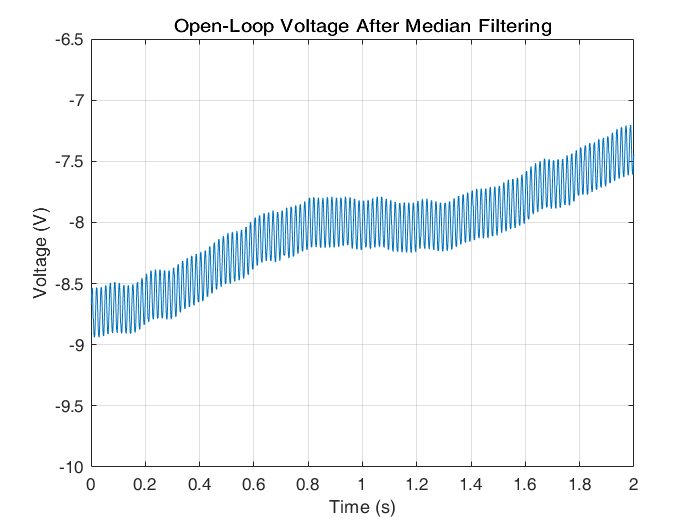

medfiltLoopVoltage = medfilt1(noisyLoopVoltage,window);

plot(t,medfiltLoopVoltage)

xlabel('Time (s)')
ylabel('Voltage (V)')
title('Open-Loop Voltage After Median Filtering')
ylim(yax);
grid on;

## Further Practice

- Try different hyperparameters values for the windows size of the moving average filter. How does the smoothed version change?

- Try different methods of smoothdata for image denoising.

- Increase the windows size of the median filter. What happens to the filtered signal?

- Try to use the moving average filter to remove spikes instead of the median filter.

## Further readings

- [movmean](https://it.mathworks.com/help/matlab/ref/movmean.html) 

- [Signal smoothing](https://it.mathworks.com/help/signal/ug/signal-smoothing.html)

- [Data smoothing and Outlier Detection](https://it.mathworks.com/help/matlab/data_analysis/data-smoothing-and-outlier-detection.html)

- [Signal Processing Onramp](https://matlabacademy.mathworks.com/R2020b/portal.html?course=signalprocessing)